clear all
close all

%WORKING IN eV

v2=5e+9;
vx=1.8e+13; %18 TeV
D=17*vx;
mt=1776.9e+6;
mu=105.65e+6;
M11=1000;
smin=0;
smax=pi/2;
r11=(v2/(2*sqrt(2)*17^3*mt));
r12=((sqrt(2)*mu)/(4*17^3*mt));
hxmin=0.01;
hxmax=0.1;

h2eevno=zeros(1,100);
h2euvno=zeros(1,100);
h2etvno=zeros(1,100);
h2uevno=zeros(1,100);
h2uuvno=zeros(1,100);
h2utvno=zeros(1,100);
hx1vno=zeros(1,100);
hx2vno=zeros(1,100);
hx3vno=zeros(1,100);
ssno=zeros(1,100);
m1vno=zeros(1,100);
m2vno=zeros(1,100);
m3vno=zeros(1,100);

h2eevio=zeros(1,100);
h2euvio=zeros(1,100);
h2etvio=zeros(1,100);
h2uevio=zeros(1,100);
h2uuvio=zeros(1,100);
h2utvio=zeros(1,100);
hx1vio=zeros(1,100);
hx2vio=zeros(1,100);
hx3vio=zeros(1,100);
ssio=zeros(1,100);
m1vio=zeros(1,100);
m2vio=zeros(1,100);
m3vio=zeros(1,100);

k=0;
z=0;
zz=0;

tic
for i=1:210000000
    hx1=hxmin+rand*(hxmax-hxmin);
    hx2=hxmin+rand*(hxmax-hxmin);
    %hx3=hxmin+rand*(hxmax-hxmin);
    h2ee=rand;
    h2eu=rand;
    h2et=rand;
    h2ue=rand;
    h2uu=rand;
    h2ut=rand;
    

    p=hx1/hx2;
    mv=((M11*v2^2)/(hx1^2*vx^2))*[h2ee^2+(h2ue^2*p^2) h2ee*h2eu+h2ue*h2uu*p^2 h2ee*h2et+h2ue*h2ut*p^2 ; h2ee*h2eu+h2ue*h2uu*p^2 h2eu^2+h2uu^2*p^2 h2eu*h2et+h2uu*h2ut*p^2 ; h2ee*h2et+h2ue*h2ut*p^2 h2eu*h2et+h2uu*h2ut*p^2 h2et^2+h2ut^2*p^2];

    [v,g]=eig(mv);
    
    eigmass=[round(abs(g(1,1)),5);round(abs(g(2,2)),5);round(abs(g(3,3)),5)];
    
    %Choose scenarios with at least two massive neutrinos
    if (eigmass(2)<eigmass(3))

    
        if ((eigmass(3)<0.055) && (eigmass(2)<0.01))
            tt=0;
            if ((abs(v(1,1))>abs(v(2,1))) && (abs(v(2,1))>abs(v(3,1))))
                if (eigmass(3)>0.044)
                    tt=1;%NO
                end
            end
            if ((abs(v(2,1))>abs(v(3,1))) && (abs(v(3,1))>abs(v(1,1))))
                if (eigmass(2)>0.007)
                    tt=2;%IO
                end
            end

            s_emu=smin+rand*(smax-smin);
            r1=r11+r12*sin(s_emu);
            r2=r1;
            
            Rl=[cos(s_emu) sin(s_emu) r1 ; -sin(s_emu) cos(s_emu) r2 ; -r1*cos(s_emu)+r2*sin(s_emu) -r2*cos(s_emu)-r1*sin(s_emu) 1];
            Upmns=Rl'*v;
            
            %Choose only acceptable values of pmns
             if (abs(Upmns(1,1))<(0.845) && (abs(Upmns(1,1))>(0.801)))
                
                if (abs(Upmns(1,2))<(0.579) && (abs(Upmns(1,2))>(0.513)))
                    
                    if (abs(Upmns(1,3))<(0.156) && (abs(Upmns(1,3))>(0.143)))
                        
                        if (abs(Upmns(2,1))<(0.507) && (abs(Upmns(2,1))>(0.233)))
                            
                            if (abs(Upmns(2,2))<(0.694) && (abs(Upmns(2,2))>(0.461)))
                                
                                if (abs(Upmns(2,3))<(0.778) && (abs(Upmns(2,3))>(0.631)))
                                    
                                    if (abs(Upmns(3,1))<(0.526) && (abs(Upmns(3,1))>(0.261)))
                                        
                                        if (abs(Upmns(3,2))<(0.701) && (abs(Upmns(3,2))>(0.471)))
                                            
                                            if (abs(Upmns(3,3))<(0.761) && (abs(Upmns(3,3))>(0.611)))
                                                if (tt==1)%choose between NO and IO
                                                    k=k+1;
                                                    h2eevno(k)=h2ee;
                                                    h2euvno(k)=h2eu;
                                                    h2etvno(k)=h2et;
                                                    h2uevno(k)=h2ue;
                                                    h2uuvno(k)=h2uu;
                                                    h2utvno(k)=h2ut;
                                                    hx1vno(k)=hx1;
                                                    hx2vno(k)=hx2;
                                                    %hx3vno(k)=hx3;
                                                    ssno(k)=s_emu;
                                                    m1vno(k)=g(1,1);
                                                    m2vno(k)=g(2,2);
                                                    m3vno(k)=g(3,3);
                                        
                                                end
                                
                                                if (tt==2)
                                                    z=z+1;
                                                    h2eevio(z)=h2ee;
                                                    h2euvio(z)=h2eu;
                                                    h2etvio(z)=h2et;
                                                    h2uevio(z)=h2ue;
                                                    h2uuvio(z)=h2uu;
                                                    h2utvio(z)=h2ut;
                                                    hx1vio(z)=hx1;
                                                    hx2vio(z)=hx2;
                                                    %hx3vio(z)=hx3;
                                                    ssio(z)=s_emu;
                                                    m1vio(z)=g(1,1);
                                                    m2vio(z)=g(2,2);
                                                    m3vio(z)=g(3,3);
                                                end
                                                
                                            end
                                        end
                                    end
                                end
                            end
                        end
                    end
                end
             end
        end
    
    else 
        zz=zz+1;
    end
    
end
toc

Elapsed time is 1218.964509 seconds.


zz

zz = 0

h2eevno

h2eevno =     0.6861    0.3261    0.6903    0.1628    0.3509    0.3597    0.8007    0.3245    0.2810    0.2795    0.3569    0.4234    0.0183    0.6445    0.7126    0.6016    0.6348    0.4528    0.5793    0.4807    0.2192    0.1607    0.8936    0.5290    0.0860    0.3776    0.4669    0.4892    0.3698    0.7967    0.4847    0.6805    0.0911    0.1368    0.7825    0.3041    0.5162    0.6787    0.6171    0.0935    0.2177    0.5870    0.6495    0.2687    0.5866    0.6503    0.6419    0.9829    0.4133    0.6184


h2euvno

h2euvno =     0.4790    0.9935    0.4814    0.1067    0.3460    0.0512    0.7201    0.0658    0.7517    0.6801    0.1605    0.3800    0.7013    0.8431    0.1705    0.5326    0.4501    0.3570    0.8083    0.3142    0.9455    0.7921    0.2263    0.4777    0.3130    0.8521    0.8443    0.5917    0.2602    0.5217    0.8835    0.9688    0.4656    0.8459    0.3853    0.1088    0.5831    0.3986    0.9159    0.4436    0.4797    0.3092    0.0843    0.3909    0.9582    0.8715    0.3187    0.8420    0.6496    0.6839


h2etvno

h2etvno =     0.6825    0.8633    0.9339    0.3897    0.6254    0.6547    0.9529    0.4045    0.4545    0.4717    0.5175    0.7223    0.8647    0.2932    0.9160    0.9836    0.4603    0.3195    0.4412    0.2908    0.6884    0.8634    0.8725    0.7408    0.3978    0.9491    0.6934    0.0561    0.5510    0.9845    0.1887    0.7332    0.6845    0.9323    0.8019    0.4249    0.0308    0.8162    0.8726    0.7547    0.2098    0.5111    0.7908    0.1225    0.5379    0.1627    0.9477    0.6677    0.2496    0.0722


h2uevno

h2uevno =     0.3782    0.0094    0.8718    0.5674    0.3353    0.5485    0.7467    0.8194    0.1335    0.0982    0.6443    0.4958    0.5282    0.7344    0.9203    0.6663    0.4394    0.5664    0.0298    0.9973    0.0074    0.3017    0.4385    0.3009    0.2494    0.3390    0.3870    0.6137    0.4868    0.4271    0.5165    0.4433    0.6390    0.2033    0.6719    0.9458    0.4405    0.8369    0.4065    0.3112    0.2405    0.8062    0.9989    0.3056    0.1453    0.0117    0.6908    0.4489    0.3355    0.2903


h2uuvno

h2uuvno =     0.1745    0.3581    0.7947    0.8267    0.5177    0.3451    0.7445    0.4429    0.7803    0.3551    0.5250    0.8458    0.9204    0.5292    0.4225    0.7326    0.2159    0.2300    0.2736    0.3552    0.8434    0.8673    0.1785    0.4325    0.4677    0.4110    0.3588    0.2095    0.6170    0.5664    0.4765    0.2723    0.8780    0.6225    0.1282    0.6538    0.2195    0.6626    0.3393    0.5660    0.2850    0.3076    0.8678    0.8861    0.6476    0.6737    0.8479    0.0215    0.9435    0.7192


h2utvno

h2utvno =     0.5293    0.5681    0.8049    0.7571    0.3903    0.4525    0.7863    0.6866    0.8312    0.3623    0.5117    0.3298    0.4817    0.9374    0.9432    0.8658    0.5453    0.8356    0.4988    0.9305    0.8716    0.6707    0.3512    0.1755    0.3433    0.0986    0.9511    0.6596    0.2713    0.0912    0.8254    0.8978    0.3005    0.4433    0.9190    0.7520    0.5669    0.7276    0.8489    0.5492    0.4788    0.8349    0.3678    0.9196    0.8843    0.7817    0.1991    0.9684    0.9837    0.8222


hx1vno

hx1vno =     0.0453    0.0576    0.0563    0.0267    0.0418    0.0578    0.0705    0.0246    0.0588    0.0824    0.0392    0.0386    0.0476    0.0960    0.0698    0.0828    0.0978    0.0356    0.0527    0.0548    0.0969    0.0985    0.0665    0.0414    0.0309    0.0520    0.0602    0.0608    0.0304    0.0590    0.0820    0.0706    0.0374    0.0722    0.0679    0.0331    0.0769    0.0701    0.0696    0.0802    0.0528    0.0843    0.0477    0.0599    0.0704    0.0906    0.0542    0.0663    0.0936    0.0696


hx2vno

hx2vno =     0.0648    0.0967    0.0976    0.0578    0.0466    0.0368    0.0767    0.0759    0.0614    0.0226    0.0514    0.0829    0.0930    0.0569    0.0803    0.0660    0.0329    0.0567    0.0325    0.0595    0.0558    0.0510    0.0380    0.0524    0.0338    0.0909    0.0614    0.0394    0.0770    0.0738    0.0475    0.0619    0.0661    0.0391    0.0579    0.0724    0.0306    0.0629    0.0620    0.0373    0.0274    0.0509    0.0927    0.0556    0.0526    0.0418    0.0751    0.0598    0.0612    0.0464


hx3vno

hx3vno =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ssno

ssno =     1.1790    0.0958    1.1346    0.9089    0.8951    1.2722    1.0098    1.0450    0.0701    0.0884    1.1841    0.9786    0.3732    1.0707    0.9973    0.9786    1.2941    1.2222    0.3007    0.9835    0.2736    0.1188    1.0581    1.0033    0.2026    0.2145    0.8323    0.9271    1.1044    1.1383    0.9491    0.9400    0.1983    0.0625    1.0211    1.2505    1.2611    1.1413    0.8916    0.2640    0.8546    0.9800    1.0148    0.1685    0.1810    0.3613    1.1425    1.2094    0.1747    0.2714


m1vno

m1vno = 	1.0e+-17 *

   -0.2489   -0.2006    0.0130   -0.0590    0.0402    0.0219   -0.1452   -0.0281    0.0188    0.0626   -0.0425    0.1981    0.2525    0.2419    0.6252   -0.0780    0.3830    0.1044   -0.2430    0.0093   -0.4184   -0.4209   -0.2573    0.3898   -0.4148   -0.1178   -0.0332    0.1961    0.2241    0.1644   -0.1372   -0.2748   -0.3932    0.2029   -0.1411   -0.3907    0.2541   -0.2866    0.0544    0.1830    0.0242   -0.4157   -0.4684   -0.0005    0.3281    0.0802    0.0727    0.1007   -0.2114   -0.3174


m1vnomax=max(m1vno)

m1vnomax = 8.4855e-18

m1vnomin=min(m1vno)

m1vnomin = -8.3647e-18

len1=length(m1vno)

len1 = 614

m1vnoprom=0;
for r=1:len1
    m1vnoprom=m1vnoprom+m1vno(r);
end
m1vnoprom/len1

ans = 5.8817e-20

m2vno

m2vno =     0.0004    0.0005    0.0008    0.0034    0.0016    0.0025    0.0001    0.0013    0.0012    0.0004    0.0021    0.0035    0.0032    0.0026    0.0004    0.0004    0.0006    0.0029    0.0071    0.0009    0.0005    0.0004    0.0003    0.0019    0.0015    0.0010    0.0031    0.0063    0.0025    0.0030    0.0045    0.0038    0.0079    0.0009    0.0009    0.0017    0.0044    0.0007    0.0018    0.0010    0.0022    0.0001    0.0063    0.0014    0.0040    0.0061    0.0071    0.0085    0.0012    0.0060


m2vnomax=max(m2vno)

m2vnomax = 0.0100

m2vnomin=min(m2vno)

m2vnomin = 3.9863e-06

m2vnoprom=0;
for r=1:len1
    m2vnoprom=m2vnoprom+m2vno(r);
end
m2vnoprom/len1

ans = 0.0027

m3vno

m3vno =     0.0517    0.0460    0.0542    0.0535    0.0453    0.0460    0.0547    0.0515    0.0448    0.0486    0.0469    0.0524    0.0512    0.0481    0.0442    0.0484    0.0443    0.0493    0.0495    0.0531    0.0476    0.0491    0.0464    0.0544    0.0468    0.0522    0.0512    0.0486    0.0491    0.0459    0.0478    0.0478    0.0529    0.0543    0.0528    0.0461    0.0499    0.0521    0.0498    0.0481    0.0445    0.0505    0.0464    0.0468    0.0542    0.0524    0.0469    0.0533    0.0452    0.0535


m3vnomax=max(m3vno)

m3vnomax = 0.0550

m3vnomin=min(m3vno)

m3vnomin = 0.0440

m3vnoprom=0;
for r=1:len1
    m3vnoprom=m3vnoprom+m3vno(r);
end
m3vnoprom/len1

ans = 0.0492




h2eevio

h2eevio =     0.6780    0.4068    0.8243    0.8765    0.0359    0.7841    0.2455    0.0015    0.4289    0.1412    0.3633    0.8411    0.5688    0.8526    0.2505    0.1233    0.1440    0.2370    0.5191    0.2316    0.1460    0.1067    0.9612    0.1673    0.8777    0.5194    0.1120    0.2138    0.8878    0.9671    0.6236    0.1999    0.0094    0.3830    0.0432    0.9046    0.1190    0.4823    0.3588    0.9399    0.9345    0.9264    0.3758    0.1160    0.4575    0.0027    0.1914    0.9435    0.0111    0.0068


h2euvio

h2euvio =     0.3900    0.0500    0.0252    0.3980    0.4341    0.1103    0.2837    0.5673    0.6010    0.2323    0.4734    0.2374    0.0245    0.0127    0.3872    0.2109    0.6193    0.2064    0.0573    0.5389    0.2227    0.3885    0.1353    0.7398    0.0512    0.5007    0.3454    0.5623    0.3873    0.3046    0.1104    0.4269    0.6452    0.4673    0.2437    0.3474    0.1352    0.3997    0.3141    0.5897    0.5335    0.1331    0.0444    0.4190    0.1093    0.1611    0.1840    0.4473    0.1858    0.3252


h2etvio

h2etvio =     0.4072    0.1068    0.6199    0.4498    0.8393    0.4131    0.8448    0.9936    0.9621    0.2900    0.9929    0.1930    0.0344    0.0043    0.7164    0.6244    0.9934    0.5122    0.0150    0.9881    0.3554    0.9693    0.0687    0.9013    0.1048    0.9149    0.9319    0.9247    0.2727    0.2491    0.3631    0.8486    0.9990    0.9281    0.4919    0.1598    0.2684    0.8377    0.7968    0.6298    0.1977    0.2087    0.0280    0.5920    0.0948    0.4577    0.5389    0.6882    0.2615    0.8274


h2uevio

h2uevio =     0.0680    0.1007    0.0367    0.1120    0.9250    0.1072    0.9982    0.7068    0.2849    0.9241    0.8895    0.3361    0.2289    0.5306    0.3792    0.5790    0.9509    0.7748    0.1306    0.5909    0.9839    0.8365    0.3507    0.9042    0.1209    0.4885    0.6152    0.7657    0.1155    0.3215    0.1933    0.6538    0.8952    0.7395    0.8670    0.3020    0.9631    0.4860    0.8207    0.0506    0.0123    0.3228    0.1624    0.4809    0.0785    0.8544    0.9335    0.0006    0.9827    0.9926


h2uuvio

h2uuvio =     0.3901    0.3397    0.3297    0.4714    0.1278    0.2851    0.1767    0.1017    0.0799    0.4277    0.1253    0.5290    0.3271    0.4976    0.0806    0.0844    0.3676    0.1967    0.3262    0.2215    0.2329    0.2500    0.6006    0.6722    0.4550    0.0211    0.2401    0.2190    0.5011    0.4636    0.4496    0.0901    0.4760    0.0943    0.1230    0.6357    0.0521    0.1396    0.2118    0.5802    0.5188    0.3809    0.5548    0.2970    0.4379    0.0729    0.1224    0.4096    0.8657    0.6237


h2utvio

h2utvio =     0.9792    0.9490    0.9884    0.8739    0.6489    0.8872    0.3536    0.1779    0.0629    0.1389    0.4839    0.8831    0.6197    0.9100    0.2112    0.1778    0.2574    0.2351    0.9767    0.2723    0.0241    0.2587    0.9813    0.1084    0.8063    0.0611    0.3886    0.1684    0.7800    0.7135    0.8539    0.4061    0.0981    0.2977    0.6459    0.9821    0.1777    0.0401    0.2775    0.9745    0.9111    0.6429    0.9476    0.1303    0.7589    0.3190    0.2763    0.7925    0.4807    0.6253


hx1vio

hx1vio =     0.0392    0.0318    0.0428    0.0682    0.0630    0.0417    0.0529    0.0988    0.0525    0.0166    0.0625    0.0589    0.0438    0.0644    0.0472    0.0503    0.0700    0.0323    0.0454    0.0605    0.0238    0.0741    0.0774    0.0502    0.0708    0.0494    0.0648    0.0610    0.0684    0.0739    0.0358    0.0549    0.0802    0.0504    0.0384    0.0693    0.0191    0.0424    0.0490    0.0633    0.0789    0.0590    0.0332    0.0407    0.0341    0.0400    0.0363    0.0578    0.0190    0.0645


hx2vio

hx2vio =     0.0631    0.0795    0.0739    0.0567    0.0598    0.0625    0.0632    0.0627    0.0208    0.0706    0.0549    0.0478    0.0420    0.0534    0.0203    0.0431    0.0733    0.0481    0.0869    0.0424    0.0897    0.0570    0.0726    0.0835    0.0720    0.0353    0.0331    0.0559    0.0622    0.0379    0.0575    0.0393    0.0798    0.0468    0.0553    0.0545    0.0777    0.0344    0.0494    0.0670    0.0672    0.0429    0.0862    0.0417    0.0607    0.0661    0.0614    0.0583    0.0770    0.0657


hx3vio

hx3vio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ssio

ssio =     0.7149    0.9937    1.2333    0.9919    1.4005    1.1124    0.9779    1.2206    1.0482    0.9216    1.3665    1.0446    1.1947    1.2157    1.3544    1.0237    0.9598    0.9391    0.9467    1.0706    0.9975    0.8943    1.1057    0.6109    1.2600    1.2183    0.8812    1.0239    1.0130    1.0183    1.3597    1.3696    0.7725    1.2745    1.4371    0.9025    1.2739    0.7944    0.9416    0.9690    0.8264    1.2680    1.1046    0.8068    1.1361    1.0632    1.0330    1.1515    0.7765    0.6916


m1vio

m1vio = 	1.0e+-16 *

    0.0048    0.0120    0.0009   -0.0194   -0.0079    0.0210   -0.0217   -0.0033   -0.0260    0.0536    0.0075    0.0290    0.0260    0.0336    0.0168   -0.0205    0.0099   -0.0163   -0.0102    0.0096    0.0453   -0.0495   -0.0098    0.0117   -0.0136    0.1204   -0.0724    0.0097   -0.0063   -0.0541   -0.0181    0.0685    0.0427    0.0614    0.0186    0.0130    0.0151   -0.0455   -0.0066   -0.0637   -0.0301   -0.0668    0.0087   -0.0177    0.0029   -0.0216    0.0024    0.0914   -0.0695    0.0467


m1viomax=max(m1vio)

m1viomax = 1.2040e-17

m1viomin=min(m1vio)

m1viomin = -1.4357e-17

len2=length(m1vio)

len2 = 217

m1vioprom=0;
for r=1:len2
    m1vioprom=m1vioprom+m1vio(r);
end
m1vioprom/len2

ans = -1.8355e-19

m2vio

m2vio =     0.0098    0.0082    0.0084    0.0076    0.0086    0.0095    0.0092    0.0076    0.0082    0.0077    0.0072    0.0095    0.0099    0.0096    0.0078    0.0074    0.0091    0.0077    0.0086    0.0078    0.0071    0.0093    0.0086    0.0086    0.0093    0.0091    0.0081    0.0098    0.0078    0.0073    0.0087    0.0085    0.0093    0.0089    0.0072    0.0093    0.0071    0.0091    0.0078    0.0079    0.0097    0.0089    0.0081    0.0073    0.0099    0.0081    0.0083    0.0081    0.0079    0.0074


m2viomax=max(m2vio)

m2viomax = 0.0099

m2viomin=min(m2vio)

m2viomin = 0.0070

m2vioprom=0;
for r=1:len2
    m2vioprom=m2vioprom+m2vio(r);
end
m2vioprom/len2

ans = 0.0083

m3vio

m3vio =     0.0510    0.0180    0.0517    0.0352    0.0366    0.0433    0.0366    0.0134    0.0493    0.0527    0.0460    0.0479    0.0270    0.0407    0.0540    0.0218    0.0287    0.0422    0.0126    0.0404    0.0295    0.0258    0.0247    0.0480    0.0158    0.0488    0.0517    0.0318    0.0263    0.0525    0.0460    0.0457    0.0202    0.0510    0.0385    0.0441    0.0272    0.0548    0.0450    0.0456    0.0239    0.0393    0.0148    0.0329    0.0216    0.0181    0.0325    0.0461    0.0394    0.0388


m3viomax=max(m3vio)

m3viomax = 0.0548

m3viomin=min(m3vio)

m3viomin = 0.0111

m3vioprom=0;
for r=1:len2
    m3vioprom=m3vioprom+m3vio(r);
end
m3vioprom/len2

ans = 0.0347

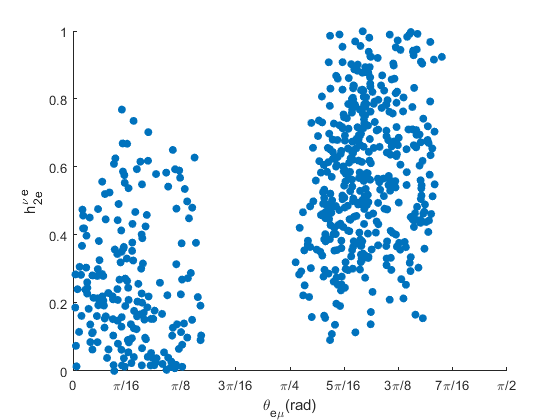


scatter(ssno,h2eevno,'filled')
xlabel('\theta_{e\mu}(rad)')
xlim([0 pi/2])
xticks([0 pi/16 pi/8 3*pi/16 pi/4 5*pi/16 3*pi/8 7*pi/16 pi/2])
xticklabels({'0','\pi/16','\pi/8','3\pi/16','\pi/4','5\pi/16','3\pi/8','7\pi/16','\pi/2'})
ylabel('h_{2e}^{\nu e}')
ylim([0 1])
yticks([0 0.2 0.4 0.6 0.8 1])

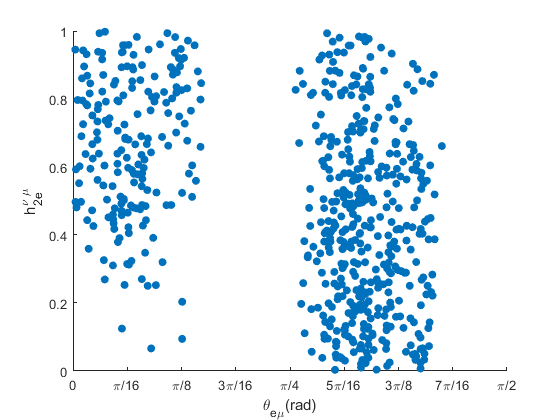


scatter(ssno,h2euvno,'filled')
xlabel('\theta_{e\mu}(rad)')
xlim([0 pi/2])
xticks([0 pi/16 pi/8 3*pi/16 pi/4 5*pi/16 3*pi/8 7*pi/16 pi/2])
xticklabels({'0','\pi/16','\pi/8','3\pi/16','\pi/4','5\pi/16','3\pi/8','7\pi/16','\pi/2'})
ylabel('h_{2e}^{\nu \mu}')
ylim([0 1])
yticks([0 0.2 0.4 0.6 0.8 1])

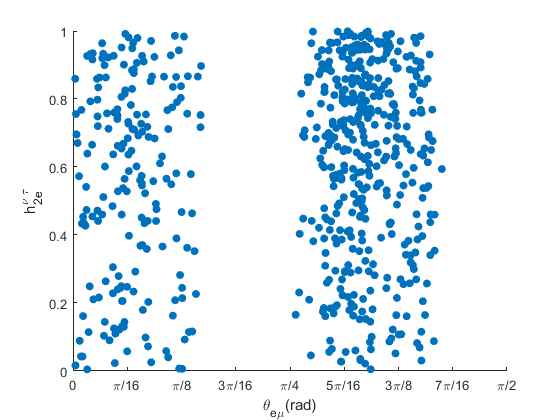


scatter(ssno,h2etvno,'filled')
xlabel('\theta_{e\mu}(rad)')
xlim([0 pi/2])
xticks([0 pi/16 pi/8 3*pi/16 pi/4 5*pi/16 3*pi/8 7*pi/16 pi/2])
xticklabels({'0','\pi/16','\pi/8','3\pi/16','\pi/4','5\pi/16','3\pi/8','7\pi/16','\pi/2'})
ylabel('h_{2e}^{\nu \tau}')
ylim([0 1])
yticks([0 0.2 0.4 0.6 0.8 1])

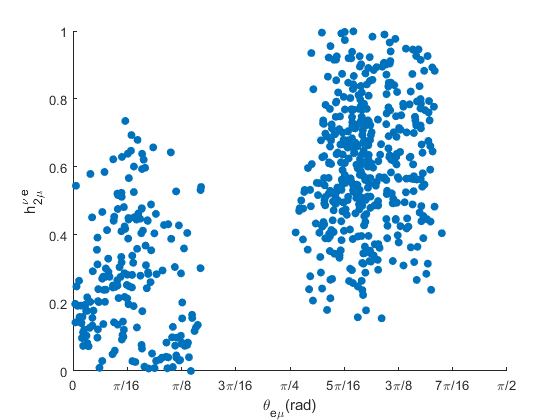


scatter(ssno,h2uevno,'filled')
xlabel('\theta_{e\mu}(rad)')
xlim([0 pi/2])
xticks([0 pi/16 pi/8 3*pi/16 pi/4 5*pi/16 3*pi/8 7*pi/16 pi/2])
xticklabels({'0','\pi/16','\pi/8','3\pi/16','\pi/4','5\pi/16','3\pi/8','7\pi/16','\pi/2'})
ylabel('h_{2\mu}^{\nu e}')
ylim([0 1])
yticks([0 0.2 0.4 0.6 0.8 1])

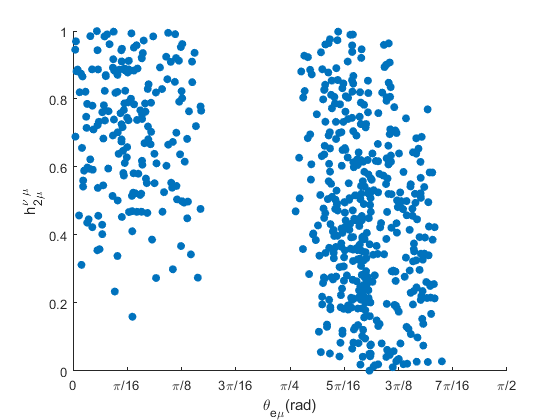


scatter(ssno,h2uuvno,'filled')
xlabel('\theta_{e\mu}(rad)')
xlim([0 pi/2])
xticks([0 pi/16 pi/8 3*pi/16 pi/4 5*pi/16 3*pi/8 7*pi/16 pi/2])
xticklabels({'0','\pi/16','\pi/8','3\pi/16','\pi/4','5\pi/16','3\pi/8','7\pi/16','\pi/2'})
ylabel('h_{2\mu}^{\nu \mu}')
ylim([0 1])
yticks([0 0.2 0.4 0.6 0.8 1])

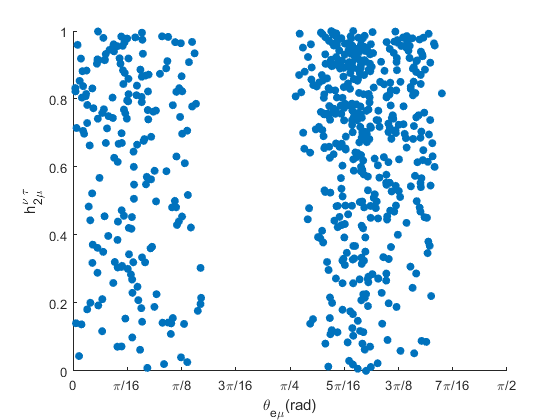


scatter(ssno,h2utvno,'filled')
xlabel('\theta_{e\mu}(rad)')
xlim([0 pi/2])
xticks([0 pi/16 pi/8 3*pi/16 pi/4 5*pi/16 3*pi/8 7*pi/16 pi/2])
xticklabels({'0','\pi/16','\pi/8','3\pi/16','\pi/4','5\pi/16','3\pi/8','7\pi/16','\pi/2'})
ylabel('h_{2\mu}^{\nu \tau}')
ylim([0 1])
yticks([0 0.2 0.4 0.6 0.8 1])

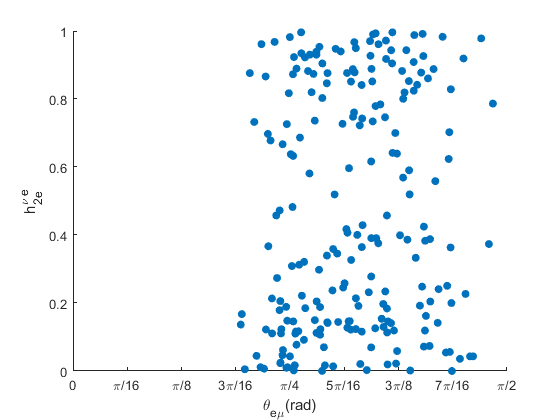



scatter(ssio,h2eevio,'filled')
xlabel('\theta_{e\mu}(rad)')
xlim([0 pi/2])
xticks([0 pi/16 pi/8 3*pi/16 pi/4 5*pi/16 3*pi/8 7*pi/16 pi/2])
xticklabels({'0','\pi/16','\pi/8','3\pi/16','\pi/4','5\pi/16','3\pi/8','7\pi/16','\pi/2'})
ylabel('h_{2e}^{\nu e}')
ylim([0 1])
yticks([0 0.2 0.4 0.6 0.8 1])

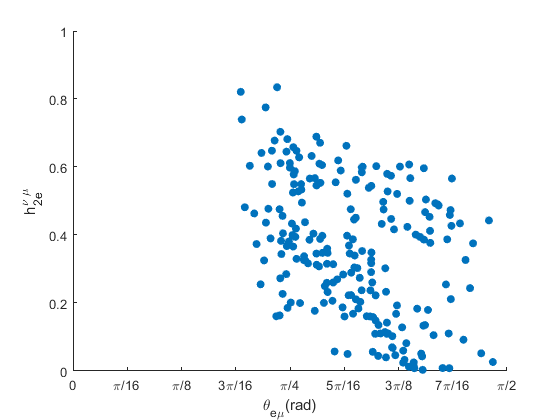


scatter(ssio,h2euvio,'filled')
xlabel('\theta_{e\mu}(rad)')
xlim([0 pi/2])
xticks([0 pi/16 pi/8 3*pi/16 pi/4 5*pi/16 3*pi/8 7*pi/16 pi/2])
xticklabels({'0','\pi/16','\pi/8','3\pi/16','\pi/4','5\pi/16','3\pi/8','7\pi/16','\pi/2'})
ylabel('h_{2e}^{\nu \mu}')
ylim([0 1])
yticks([0 0.2 0.4 0.6 0.8 1])

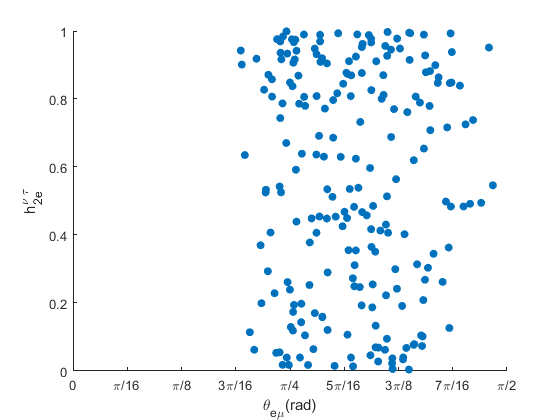


scatter(ssio,h2etvio,'filled')
xlabel('\theta_{e\mu}(rad)')
xlim([0 pi/2])
xticks([0 pi/16 pi/8 3*pi/16 pi/4 5*pi/16 3*pi/8 7*pi/16 pi/2])
xticklabels({'0','\pi/16','\pi/8','3\pi/16','\pi/4','5\pi/16','3\pi/8','7\pi/16','\pi/2'})
ylabel('h_{2e}^{\nu \tau}')
ylim([0 1])
yticks([0 0.2 0.4 0.6 0.8 1])

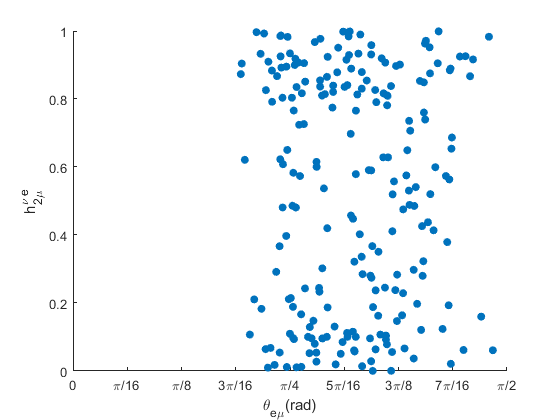


scatter(ssio,h2uevio,'filled')
xlabel('\theta_{e\mu}(rad)')
xlim([0 pi/2])
xticks([0 pi/16 pi/8 3*pi/16 pi/4 5*pi/16 3*pi/8 7*pi/16 pi/2])
xticklabels({'0','\pi/16','\pi/8','3\pi/16','\pi/4','5\pi/16','3\pi/8','7\pi/16','\pi/2'})
ylabel('h_{2\mu}^{\nu e}')
ylim([0 1])
yticks([0 0.2 0.4 0.6 0.8 1])

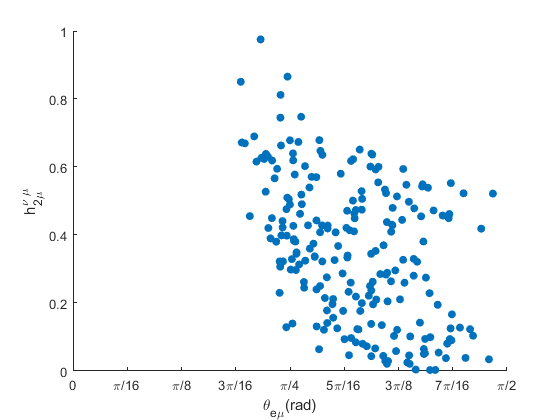


scatter(ssio,h2uuvio,'filled')
xlabel('\theta_{e\mu}(rad)')
xlim([0 pi/2])
xticks([0 pi/16 pi/8 3*pi/16 pi/4 5*pi/16 3*pi/8 7*pi/16 pi/2])
xticklabels({'0','\pi/16','\pi/8','3\pi/16','\pi/4','5\pi/16','3\pi/8','7\pi/16','\pi/2'})
ylabel('h_{2\mu}^{\nu \mu}')
ylim([0 1])
yticks([0 0.2 0.4 0.6 0.8 1])

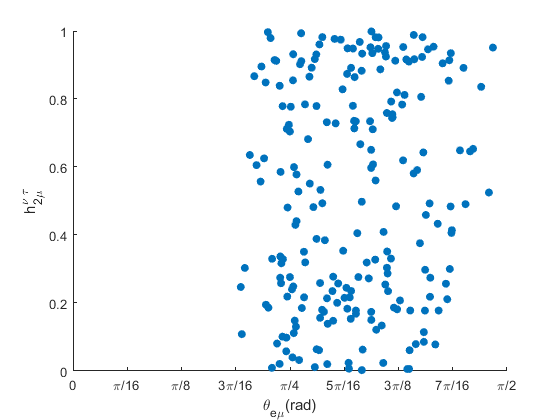


scatter(ssio,h2utvio,'filled')
xlabel('\theta_{e\mu}(rad)')
xlim([0 pi/2])
xticks([0 pi/16 pi/8 3*pi/16 pi/4 5*pi/16 3*pi/8 7*pi/16 pi/2])
xticklabels({'0','\pi/16','\pi/8','3\pi/16','\pi/4','5\pi/16','3\pi/8','7\pi/16','\pi/2'})
ylabel('h_{2\mu}^{\nu \tau}')
ylim([0 1])
yticks([0 0.2 0.4 0.6 0.8 1])